# Analysis

pilot data from the 'counterfactual stimuli' experiment.

## Load data

data_struct = loadData;
subj_list = data_struct.keys;

## Accuracy

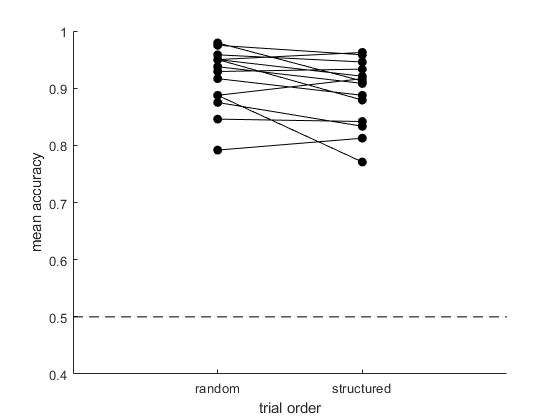

[rand_acc,struct_acc] = deal(nan(size(subj_list)));
for i_s = 1:numel(subj_list)
    subj = data_struct(subj_list{i_s});
    rand_acc(i_s) = nanmean(subj.RandomCorrect);
    struct_acc(i_s) = nanmean(subj.StructCorrect);
end

figure; hold on;
plot([rand_acc;struct_acc],'-ok','MarkerFaceColor','k');
ylabel('mean accuracy');
xlim([0,3]); xlabel('trial order');
ylim([0.4,1]);
plot([0,3],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});


%check significance
[h,p,ci,stats] = ttest(rand_acc-struct_acc)

h = 1

p = 0.0349

ci =     0.0021    0.0479


stats = struct with fields:
    tstat: 2.3544
       df: 13
       sd: 0.0397



sprintf('we found a significant difference between the two conditions t(%d)=%.2f, p=%.3f',stats.df,stats.tstat,p)

ans = 'we found a significant difference between the two conditions t(13)=2.35, p=0.035'

## Response bias

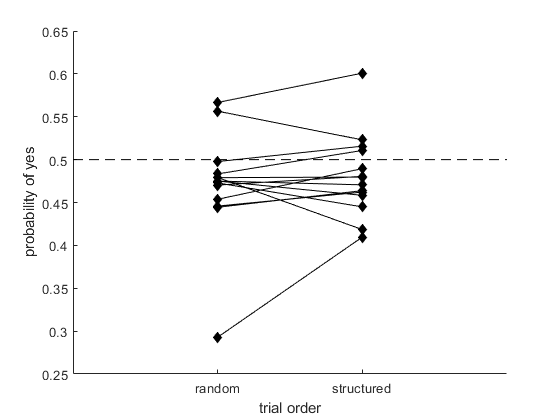

[rand_pyes,struct_pyes] = deal(nan(size(subj_list)));
for i_s = 1:numel(subj_list)
    subj = data_struct(subj_list{i_s});
    rand_pyes(i_s) = nanmean(subj.RandomResp);
    struct_pyes(i_s) = nanmean(subj.StructResp);
end

figure; hold on;
plot([rand_pyes;struct_pyes],'-dk','MarkerFaceColor','k');
ylabel('probability of yes');
xlim([0,3]); xlabel('trial order');
plot([0,3],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});


%check significance
[h,p,ci,stats] = ttest(rand_pyes-struct_pyes);
[h_r,p_r,ci_r,stats_r] = ttest(rand_pyes-0.5);
[h_s,p_s,ci_s,stats_s] = ttest(struct_pyes-0.5);
sprintf('we found no significant difference between the two conditions t(%d)=%.2f, p=%.3f',stats.df,stats.tstat,p)

ans = 'we found no significant difference between the two conditions t(13)=-0.87, p=0.400'

## Confidence

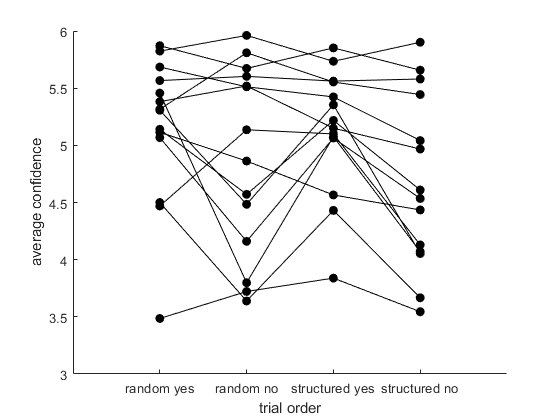

[rand_yes_conf,struct_yes_conf, rand_no_conf, struct_no_conf] = deal(nan(size(subj_list)));
for i_s = 1:numel(subj_list)
    subj = data_struct(subj_list{i_s});
    rand_yes_conf(i_s) = nanmean(subj.RandomConf(subj.RandomResp==1));
    struct_yes_conf(i_s) = nanmean(subj.StructConf(subj.StructResp==1));
    rand_no_conf(i_s) = nanmean(subj.RandomConf(subj.RandomResp==0));
    struct_no_conf(i_s) = nanmean(subj.StructConf(subj.StructResp==0));
end

figure; hold on;
plot([rand_yes_conf;rand_no_conf;struct_yes_conf;struct_no_conf],'-ok','MarkerFaceColor','k');
ylabel('average confidence');
xlim([0,5]); xlabel('trial order');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no', 'structured yes','structured no'});

## Visibility-confidence correlation

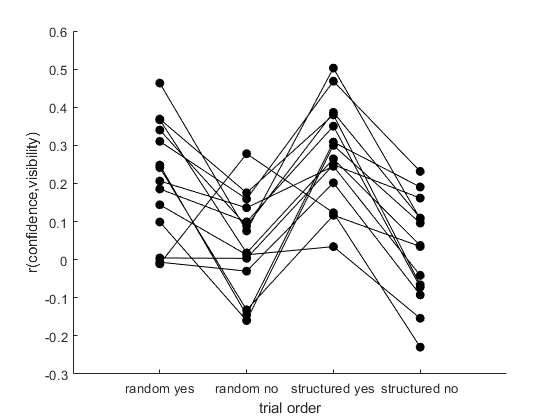

[rand_yes_corr,struct_yes_corr, rand_no_corr, struct_no_corr] = deal(nan(size(subj_list)));
for i_s = 1:numel(subj_list)
    subj = data_struct(subj_list{i_s});
    
    demeaned_random_confidence = ...
        [subj.RandomConf(1:120)-mean(subj.RandomConf(1:120)); subj.RandomConf(121:240)-mean(subj.RandomConf(121:240))];
        
    demeaned_struct_confidence = ...
        [subj.StructConf(1:120)-mean(subj.StructConf(1:120)); subj.StructConf(121:240)-mean(subj.StructConf(121:240))];
        
    rand_yes_corr(i_s) = nancorr(demeaned_random_confidence(subj.RandomResp==1 & subj.RandomCorrect==1),...
        subj.RandomVisibility(subj.RandomResp==1 & subj.RandomCorrect==1));
    struct_yes_corr(i_s) = nancorr(demeaned_struct_confidence(subj.StructResp==1 & subj.StructCorrect==1),...
        subj.StructVisibility(subj.StructResp==1 & subj.StructCorrect==1));
    
    rand_no_corr(i_s) = nancorr(demeaned_random_confidence(subj.RandomResp==0 & subj.RandomCorrect==1),...
        subj.RandomVisibility(subj.RandomResp==0 & subj.RandomCorrect==1));
    struct_no_corr(i_s) = nancorr(demeaned_struct_confidence(subj.StructResp==0 & subj.StructCorrect==1),...
        subj.StructVisibility(subj.StructResp==0 & subj.StructCorrect==1));
end

figure; hold on;
plot([rand_yes_corr;rand_no_corr;struct_yes_corr;struct_no_corr],'-ok','MarkerFaceColor','k');
ylabel('r(confidence,visibility)');
xlim([0,5]); xlabel('trial order');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no', 'structured yes','structured no'});